# Marim Elhanafy 201803468 

# Reham Eshbair 201701979

# Asma Alnaimi 201678057

# In Lab 2

**Design a system that can detect falls:** 

1. Acquire motion data from mobile phone where it shows a simulation of the different  motion states.  

Done using Reham's phone.

- Walking (no fall)

- Putting phone down (no fall)

- Sitting (no fall)

- Fall

2. Analyze the signals in time and frequency domain and write your observations. 

close all; clear; clc;
% Read Files:
walking = csvread('Walking.csv',1,1);
putting_down = csvread('Putting Down.csv',1,1);
sitting = csvread('Sitting.csv',1,1);
falling = csvread('Falling.csv',1,1);

Time Domain:

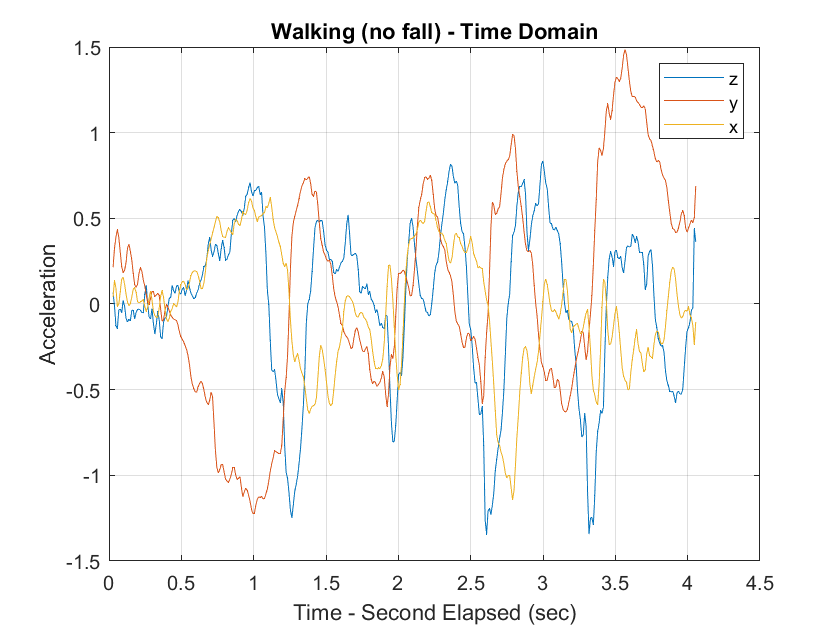

% 1. Walking
t_walking = walking(:,1);
z_walking = walking(:,2);
y_walking = walking(:,3);
x_walking = walking(:,4);
% Plot 
figure, plot(t_walking,z_walking,t_walking,y_walking,t_walking,x_walking);
xlabel('Time - Second Elapsed (sec)'); ylabel('Acceleration');
title('Walking (no fall) - Time Domain'); grid on;
legend('z','y','x');

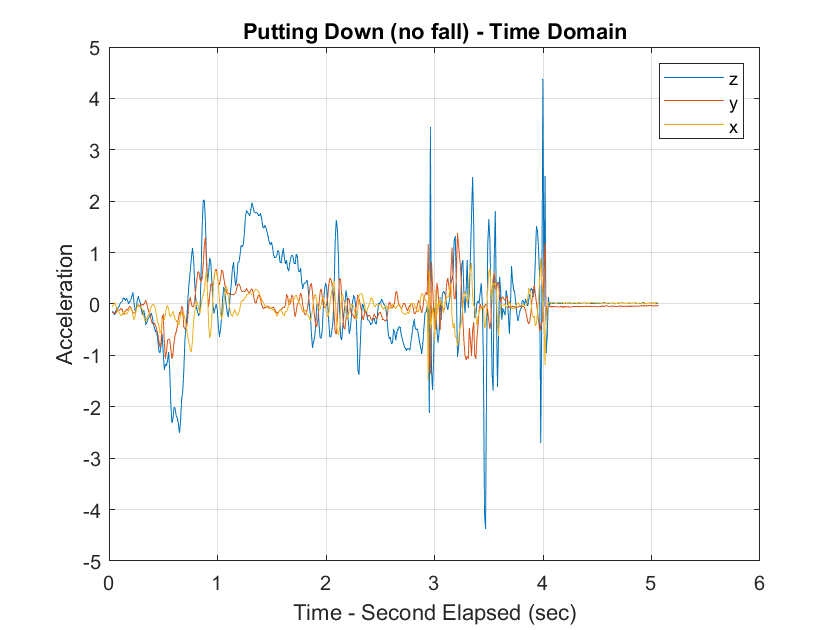

% 2. Putting Down
t_putting_down = putting_down(:,1);
z_putting_down = putting_down(:,2);
y_putting_down = putting_down(:,3);
x_putting_down = putting_down(:,4);
% Plot 
figure, plot(t_putting_down,z_putting_down,t_putting_down,y_putting_down,t_putting_down,x_putting_down);
xlabel('Time - Second Elapsed (sec)'); ylabel('Acceleration');
title('Putting Down (no fall) - Time Domain'); grid on;
legend('z','y','x');

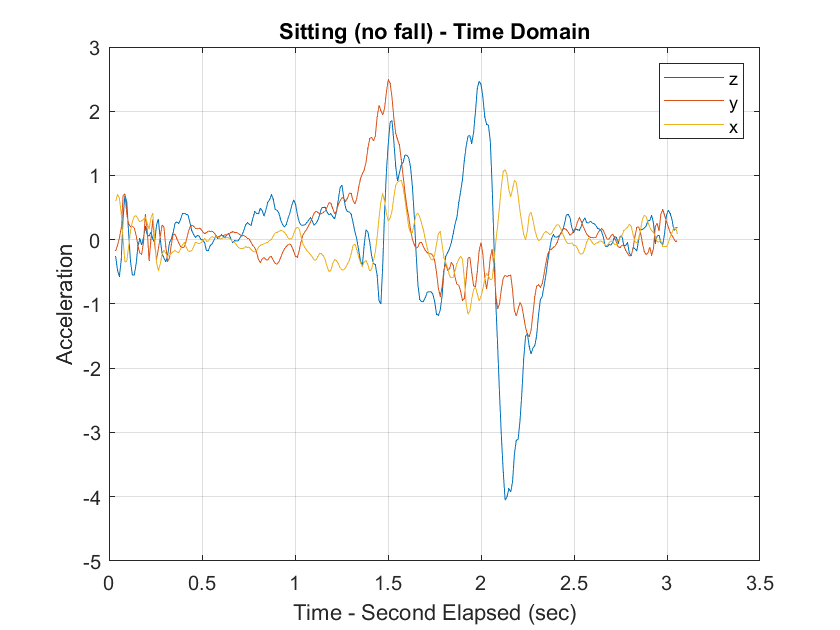

% 3. Sitting
t_sitting = sitting(:,1);
z_sitting = sitting(:,2);
y_sitting = sitting(:,3);
x_sitting = sitting(:,4);
% Plot 
figure, plot(t_sitting,z_sitting,t_sitting,y_sitting,t_sitting,x_sitting);
xlabel('Time - Second Elapsed (sec)'); ylabel('Acceleration');
title('Sitting (no fall) - Time Domain'); grid on;
legend('z','y','x');

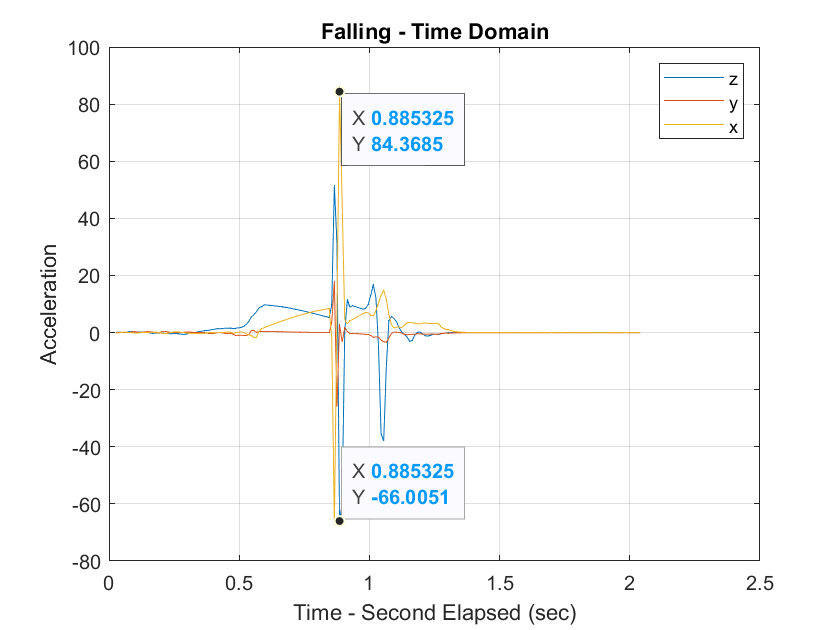

% 4. Falling
t_falling = falling(:,1);
z_falling = falling(:,2);
y_falling = falling(:,3);
x_falling = falling(:,4);
% Plot 
figure, plot(t_falling,z_falling,t_falling,y_falling,t_falling,x_falling);
xlabel('Time - Second Elapsed (sec)'); ylabel('Acceleration');
title('Falling - Time Domain'); grid on;
legend('z','y','x');

Observation for time domain:

In the first three (no fall) situations, the acceleration maximum range was small between -1.5 and 1.5 for walking, -4.5 to 4.5 for putting down, and -4 to 2.5 for sitting. While the acceleration maximum range for the falling was large which is from -66 to 84. Our second observation is that for the walking, the signal was almost uniform, and this is logic because the walking is a uniform movement.

Frequency Domain:

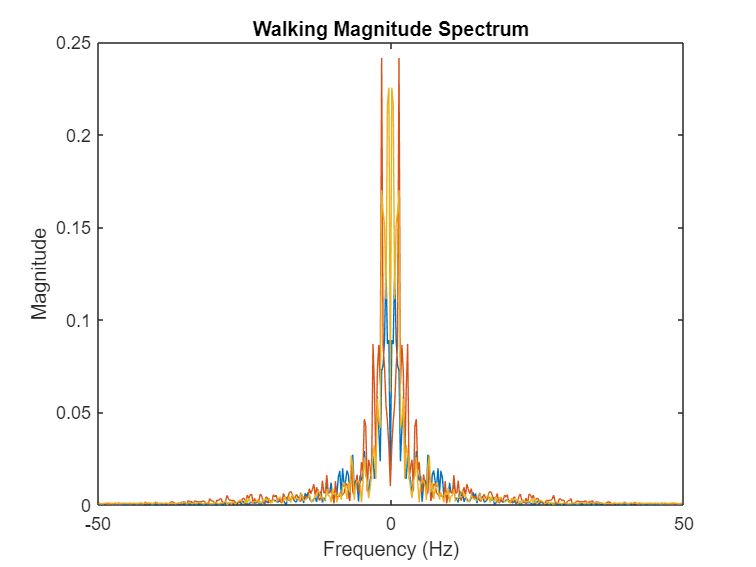

% 1. Walking:
walking_concat = [z_walking y_walking x_walking];
N_w = length(walking_concat);
Y_w = fftshift(fft(walking_concat,N_w));
Y_mag_w = abs(Y_w/N_w);
Y_ph_w = angle(Y_w);
Y_power_w = Y_mag_w.^2;
% f-axis
T_w = max(walking(:,1));
Fs_w = N_w/T_w;
df_w = Fs_w/N_w; % Resolution in the frequency domain
f_w = -Fs_w/2:df_w:Fs_w/2-df_w;
% Plot
figure, plot(f_w,Y_mag_w);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Walking Magnitude Spectrum');

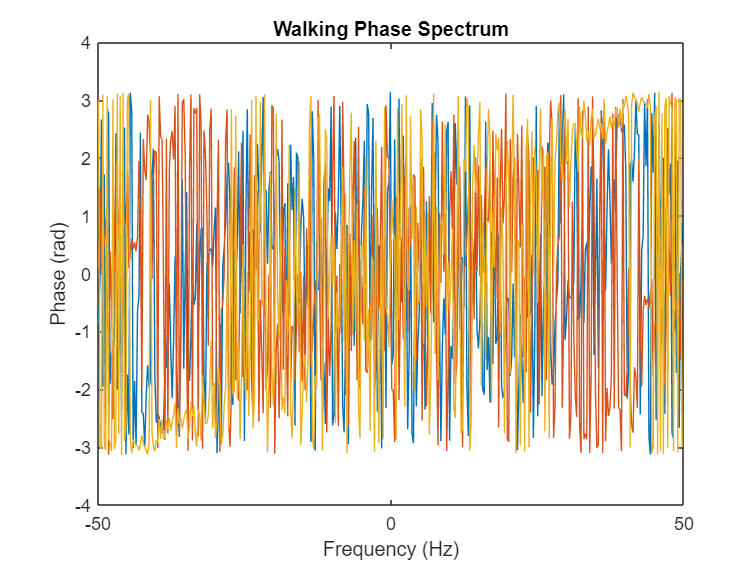

figure, plot(f_w,Y_ph_w);
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title('Walking Phase Spectrum');

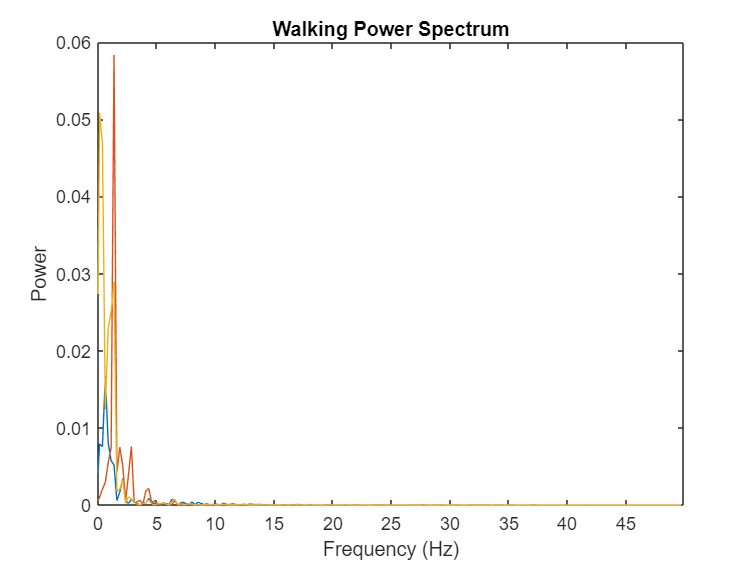

figure, plot(f_w,Y_power_w); xlim([0 Fs_w/2]);
xlabel('Frequency (Hz)'); ylabel('Power');
title('Walking Power Spectrum');

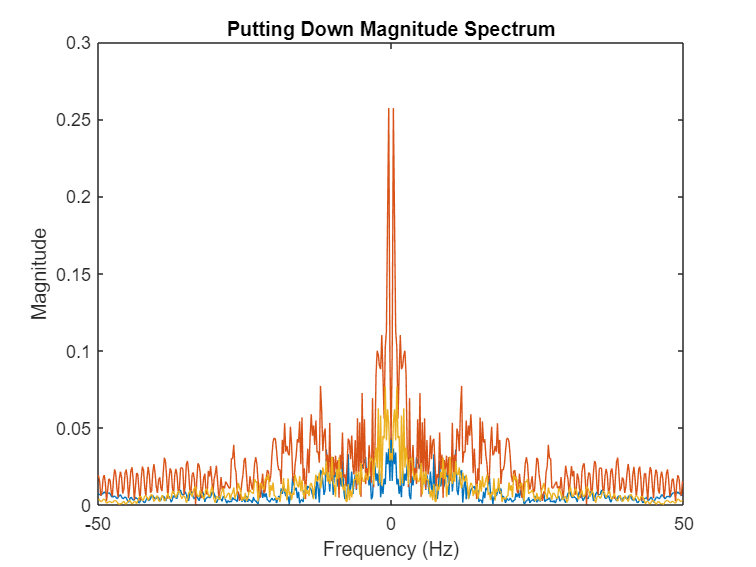

% 2. Putting Down:
putting_concat = [z_putting_down y_putting_down x_putting_down];
N_p = length(putting_concat);
Y_p = fftshift(fft(putting_concat,N_p));
Y_mag_p = abs(Y_p/N_p);
Y_ph_p = angle(Y_p);
Y_power_p = Y_mag_p.^2;
% f-axis
T_p = max(putting_down(:,1));
Fs_p = N_p/T_p;
df_p = Fs_p/N_p; % Resolution in the frequency domain
f_p = -Fs_p/2:df_p:Fs_p/2-df_p;
% Plot
figure, plot(f_p,Y_mag_p);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Putting Down Magnitude Spectrum');

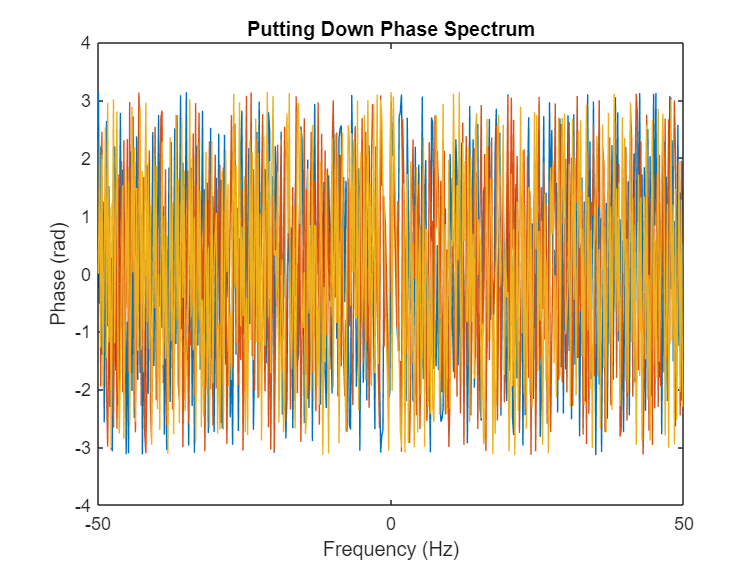

figure, plot(f_p,Y_ph_p);
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title('Putting Down Phase Spectrum');

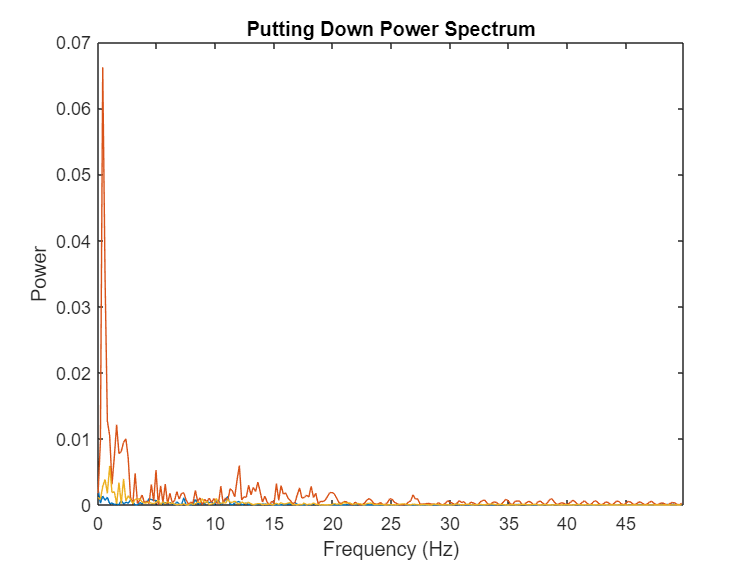

figure, plot(f_p,Y_power_p); xlim([0 Fs_p/2]);
xlabel('Frequency (Hz)'); ylabel('Power');
title('Putting Down Power Spectrum');

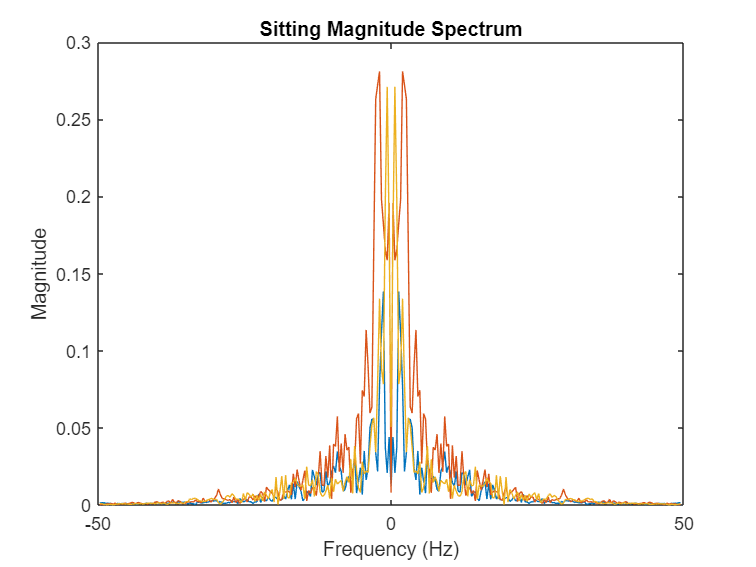

% 3. Sitting:
sitting_concat = [z_sitting y_sitting x_sitting];
N_s = length(sitting_concat);
Y_s = fftshift(fft(sitting_concat,N_s));
Y_mag_s = abs(Y_s/N_s);
Y_ph_s = angle(Y_s);
Y_power_s = Y_mag_s.^2;
% f-axis
T_s = max(sitting(:,1));
Fs_s = N_s/T_s;
df_s = Fs_s/N_s; % Resolution in the frequency domain
f_s = -Fs_s/2:df_s:Fs_s/2-df_s;
% Plot
figure, plot(f_s,Y_mag_s);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Sitting Magnitude Spectrum');

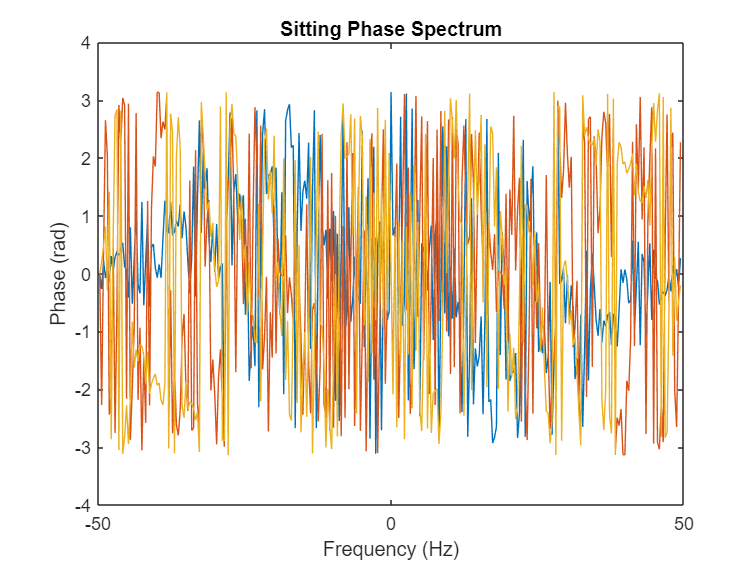

figure, plot(f_s,Y_ph_s);
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title('Sitting Phase Spectrum');

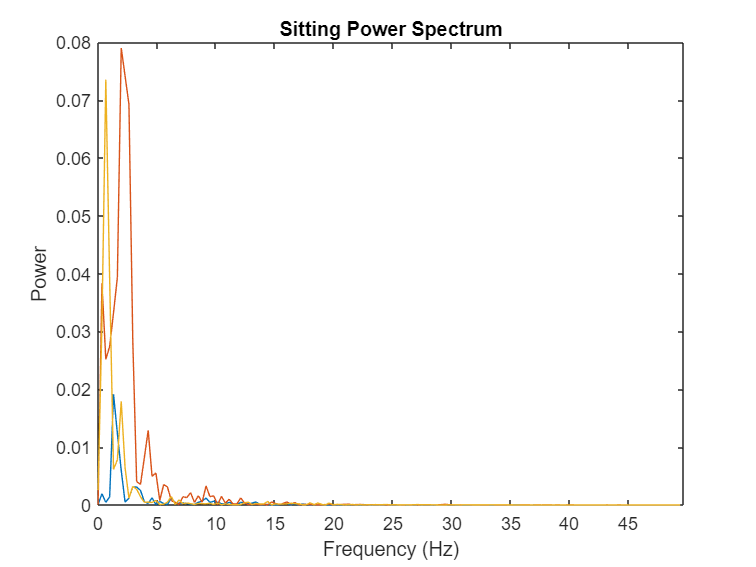

figure, plot(f_s,Y_power_s); xlim([0 Fs_s/2]);
xlabel('Frequency (Hz)'); ylabel('Power');
title('Sitting Power Spectrum');

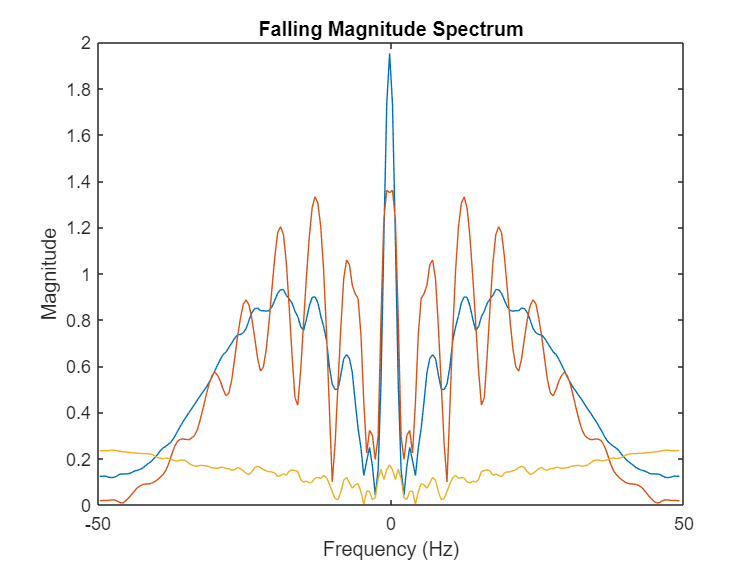

% 4. Falling:
falling_concat = [z_falling y_falling x_falling];
N_f = length(falling_concat);
Y_f = fftshift(fft(falling_concat,N_f));
Y_mag_f = abs(Y_f/N_f);
Y_ph_f = angle(Y_f);
Y_power_f = Y_mag_f.^2;
% f-axis
T_f = max(falling(:,1));
Fs_f = N_f/T_f;
df_f = Fs_f/N_f; % Resolution in the frequency domain
f_f = -Fs_f/2:df_f:Fs_f/2-df_f;
% Plot
figure, plot(f_f,Y_mag_f);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Falling Magnitude Spectrum');

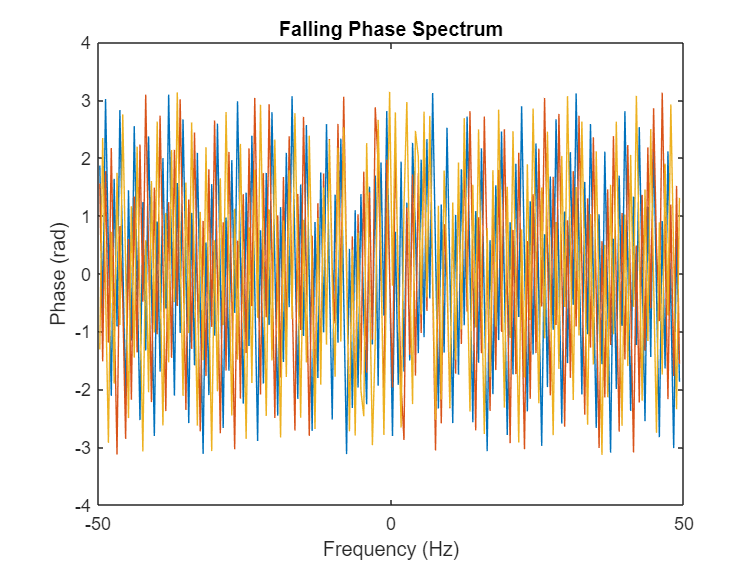

figure, plot(f_f,Y_ph_f);
xlabel('Frequency (Hz)'); ylabel('Phase (rad)');
title('Falling Phase Spectrum');

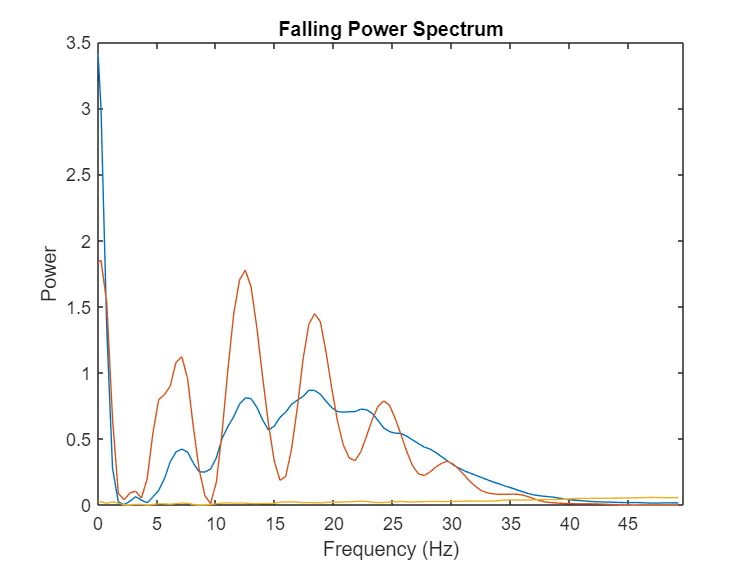

figure, plot(f_f,Y_power_f); xlim([0 Fs_f/2]);
xlabel('Frequency (Hz)'); ylabel('Power');
title('Falling Power Spectrum');

Observation for frequency domain:

First, we observed that both phase and power spectrum will not be efficient to observe the difference between the situations, because the yellow (x) is not appearing clearly in both falling and putting down. Second observation, the magnitude spectrum was very clear to observe the differnces. First, the orange (y) in walking, putting, and sitting situations were very close to each other around 0.2, while the falling case is higher magnitude, witch is 1.4. Second, the difference also appears in the blue (z), the magnitude of all (no fall) situations was almost zero, while in the fallling situation it was almost 2.

3. Based on observations, implement a DSP algorithm that can process the motion data  and detect the fall and the time of the fall (if any) to inform the user in MATLAB.

We will implement the DSP algorithm on the frequency domain. First, in the no fall situations the maximum magnitude was 0.3, while for falling was 2. So, to select our threshold, we calculated it as following: (2 - 0.3) / 2 = 0.85, and for safety we will choose our threshold to be 0.9. So, if the magnitude is higher than 0.9 we will assume it as a falling situation.

detect_motion(Y_mag_w,t_walking); % No output (no detected motion)

No Motion


detect_motion(Y_mag_p,t_putting_down);% No output (no detected motion)

No Motion


detect_motion(Y_mag_s,t_sitting);% No output (no detected motion)

No Motion


detect_motion(Y_mag_f,t_falling);